# Programmentwurf – Simulationstechnik (TSA24)

clear; clc; close all;


## Gemeinsame Parameter (aus Aufgabenstellung)

p.m  = 2000;        % Masse [kg]
p.Jz = 4000;        % Gierrträgheit [kg m^2]
p.lf = 1.43;        % Abstand SP -> Vorderachse [m]
p.lr = 1.40;        % Abstand SP -> Hinterachse [m]
p.cf = 70000;       % Schräglaufsteifigkeit VA [N/rad]
p.cr = 140000;      % Schräglaufsteifigkeit HA [N/rad]

% Simulationseinstellungen
tEnd = 8;           % Simulationszeit [s]
x0   = [0; 0];      % Anfangszustand: [beta; r] = [Schwimmwinkel; Giergeschw.]


## Einspurmodell

function dx = bicycle_nonlinear_ode(~, x, delta, v, p)
    % Zustände
    beta = x(1);   % Schwimmwinkel [rad]
    r    = x(2);   % Giergeschwindigkeit [rad/s]    
    
    cb = cos(beta); % Hilfsvariable um weniger tippen zu müssen

    % Schräglaufwinkel
    alpha_f = delta - (p.lf * r) / (v * cb) + tan(beta);
    alpha_r = (p.lr * r) / (v * cb) - tan(beta);

    % Reifen-Seitenkräfte (linearer Reifenansatz über Schräglaufsteifigkeit)
    Fy_f = p.cf * alpha_f;
    Fy_r = p.cr * alpha_r;

  
    beta_dot = -r + (1/(p.m * v)) * ( (Fy_f * cos(delta) / cb) + (Fy_r / cb) );
    r_dot    = (1/p.Jz) * ( p.lf * Fy_f * cos(delta) - p.lr * Fy_r );

    dx = [beta_dot; r_dot];
end

## Aufgabe 1 – Nichtlineares Modell in Matlab (ODE)

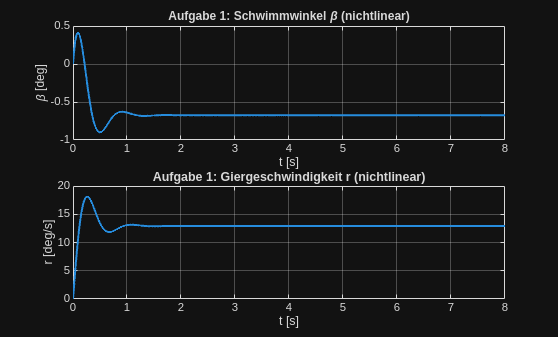


% Lenkwinkelsprung: delta = 5°; Geschwindigkeit v = 18 m/s (wie angegeben)
v = 18;                         % [m/s]
delta_deg = 5;                  % [deg]
delta = deg2rad(delta_deg);     % [rad]

% ODE lösen
odefun = @(t,x) bicycle_nonlinear_ode(t, x, delta, v, p);

opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(odefun, [0 tEnd], x0, opts);

beta = x(:,1);      % Schwimmwinkel [rad]
r    = x(:,2);      % Giergeschwindigkeit [rad/s]

% Plot (in ° bzw. °/s) - Zusammengefasst in einem Fenster
figure('Name', 'Aufgabe 1: Nichtlineares Einspurmodell');

subplot(2,1,1);
plot(t, rad2deg(beta), 'LineWidth', 1.5);
grid on; 
xlabel('t [s]'); 
ylabel('\beta [deg]');
title('Aufgabe 1: Schwimmwinkel \beta (nichtlinear)');

subplot(2,1,2);
plot(t, rad2deg(r), 'LineWidth', 1.5);
grid on; 
xlabel('t [s]'); 
ylabel('r [deg/s]');
title('Aufgabe 1: Giergeschwindigkeit r (nichtlinear)');

## Aufgabe 2

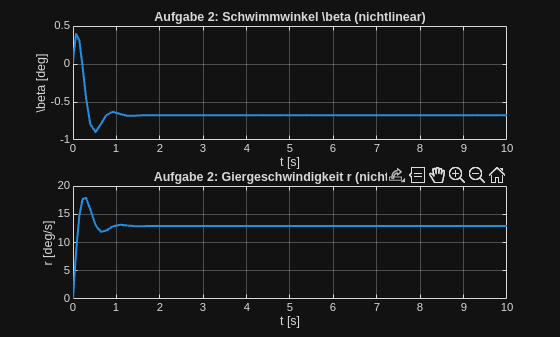

%sim("Aufgabe2_2369656.slx")

figure('Name', 'Aufgabe 2: Nichtlineares Einspurmodell');

subplot(2,1,1);
plot(out.beta, 'LineWidth', 1.5);
grid on; 
xlabel('t [s]'); 
ylabel('\beta [deg]');
title('Aufgabe 2: Schwimmwinkel \beta (nichtlinear)');

subplot(2,1,2);
plot(out.dpsi, 'LineWidth', 1.5);
grid on; 
xlabel('t [s]'); 
ylabel('r [deg/s]');
title('Aufgabe 2: Giergeschwindigkeit r (nichtlinear)');

## Aufgabe3

%% Aufgabe 3 - Linearisierung und Vergleich (5° vs. 20°) - VOLLSTÄNDIG

% 1. Systemmatrizen (bereits definiert)
A11 = (p.cf - p.cr) / (p.m * v);
A12 = (p.cr * p.lr - p.cf * p.lf) / (p.m * v^2) - 1;
A21 = (p.lf * p.cf + p.lr * p.cr) / p.Jz;
A22 = -(p.lf^2 * p.cf + p.lr^2 * p.cr) / (p.Jz * v);
A = [A11, A12; A21, A22];

B1 = p.cf / (p.m * v);
B2 = (p.lf * p.cf) / p.Jz;
B = [B1; B2];

C = eye(2); 
D = [0; 0];

sys_lin = ss(A, B, C, D);
t_sim = linspace(0, tEnd, 1000);

%% --- Vergleich für delta = 5° ---
delta5 = deg2rad(5);
u5 = delta5 * ones(size(t_sim));

% Lineare Simulation
[y_lin_5, ~] = lsim(sys_lin, u5, t_sim, x0);
beta_lin_5 = y_lin_5(:, 1);
r_lin_5    = y_lin_5(:, 2); % Zweite Spalte ist Giergeschwindigkeit

% Nichtlineare Simulation
odefun_5 = @(t,x) bicycle_nonlinear_ode(t, x, delta5, v, p);
[~, x_nl_5] = ode45(odefun_5, t_sim, x0);
beta_nl_5 = x_nl_5(:, 1);
r_nl_5    = x_nl_5(:, 2);

%% --- Vergleich für delta = 20° ---
delta20 = deg2rad(20);
u20 = delta20 * ones(size(t_sim));

% Lineare Simulation
[y_lin_20, ~] = lsim(sys_lin, u20, t_sim, x0);
beta_lin_20 = y_lin_20(:, 1);
r_lin_20    = y_lin_20(:, 2);

% Nichtlineare Simulation
odefun_20 = @(t,x) bicycle_nonlinear_ode(t, x, delta20, v, p);
[~, x_nl_20] = ode45(odefun_20, t_sim, x0);
beta_nl_20 = x_nl_20(:, 1);
r_nl_20    = x_nl_20(:, 2);

%% 4. Auswertung und Plots

% Maximale Abweichungen berechnen
max_err_beta_5  = max(abs(beta_nl_5 - beta_lin_5));
max_err_r_5     = max(abs(r_nl_5 - r_lin_5));
max_err_beta_20 = max(abs(beta_nl_20 - beta_lin_20));
max_err_r_20    = max(abs(r_nl_20 - r_lin_20));

fprintf('--- Abweichungen bei 5° ---\n');

--- Abweichungen bei 5° ---


fprintf('Schwimmwinkel:      %.4f°\n', rad2deg(max_err_beta_5));

Schwimmwinkel:      0.0033°


fprintf('Giergeschwindigkeit: %.4f°/s\n\n', rad2deg(max_err_r_5));

Giergeschwindigkeit: 0.0571°/s




fprintf('--- Abweichungen bei 20° ---\n');

--- Abweichungen bei 20° ---


fprintf('Schwimmwinkel:      %.4f°\n', rad2deg(max_err_beta_20));

Schwimmwinkel:      0.1955°


fprintf('Giergeschwindigkeit: %.4f°/s\n\n', rad2deg(max_err_r_20));

Giergeschwindigkeit: 3.6399°/s



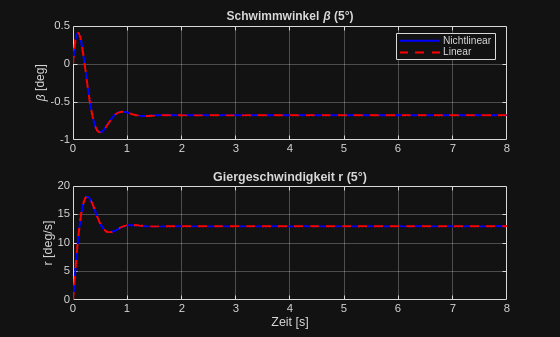


% Plot für 5 Grad
figure('Name', 'Aufgabe 3: Vergleich bei 5°');
subplot(2,1,1);
plot(t_sim, rad2deg(beta_nl_5), 'b', 'LineWidth', 1.5); hold on;
plot(t_sim, rad2deg(beta_lin_5), 'r--', 'LineWidth', 1.5);
grid on; ylabel('\beta [deg]'); title('Schwimmwinkel \beta (5°)');
legend('Nichtlinear', 'Linear');

subplot(2,1,2);
plot(t_sim, rad2deg(r_nl_5), 'b', 'LineWidth', 1.5); hold on;
plot(t_sim, rad2deg(r_lin_5), 'r--', 'LineWidth', 1.5);
grid on; xlabel('Zeit [s]'); ylabel('r [deg/s]'); title('Giergeschwindigkeit r (5°)');

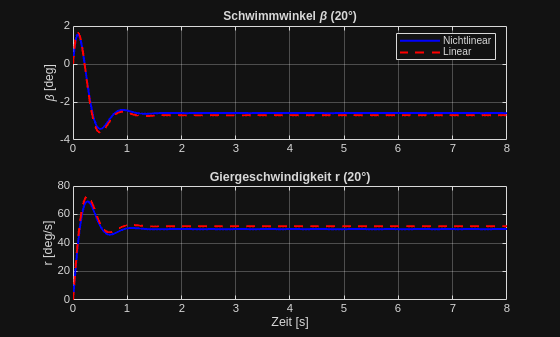


% Plot für 20 Grad
figure('Name', 'Aufgabe 3: Vergleich bei 20°');
subplot(2,1,1);
plot(t_sim, rad2deg(beta_nl_20), 'b', 'LineWidth', 1.5); hold on;
plot(t_sim, rad2deg(beta_lin_20), 'r--', 'LineWidth', 1.5);
grid on; ylabel('\beta [deg]'); title('Schwimmwinkel \beta (20°)');
legend('Nichtlinear', 'Linear');

subplot(2,1,2);
plot(t_sim, rad2deg(r_nl_20), 'b', 'LineWidth', 1.5); hold on;
plot(t_sim, rad2deg(r_lin_20), 'r--', 'LineWidth', 1.5);
grid on; xlabel('Zeit [s]'); ylabel('r [deg/s]'); title('Giergeschwindigkeit r (20°)');

## Auufgabe 3 Simulink

%% Aufgabe 3: Simulink-Modell automatisiert ausführen und vergleichen (Komplett)

modellName = 'Aufgabe3_Simulink'; 

% ==========================================
% 1. Durchlauf: 5 Grad Lenkwinkelsprung
% ==========================================
delta_sim = deg2rad(5); 

% Simulink-Modell starten
out_5 = sim(modellName);

% Abweichungen auslesen
err_beta_5 = out_5.max_fehler_beta(end);
err_dpsi_5 = out_5.max_fehler_dpsi(end);

fprintf('--- Ergebnisse bei 5° Lenkwinkelsprung ---\n');

--- Ergebnisse bei 5° Lenkwinkelsprung ---


fprintf('Max. Abweichung Schwimmwinkel:      %.4f°\n', err_beta_5);

Max. Abweichung Schwimmwinkel:      0.0019°


fprintf('Max. Abweichung Giergeschwindigkeit: %.4f°/s\n\n', err_dpsi_5);

Max. Abweichung Giergeschwindigkeit: 0.0316°/s



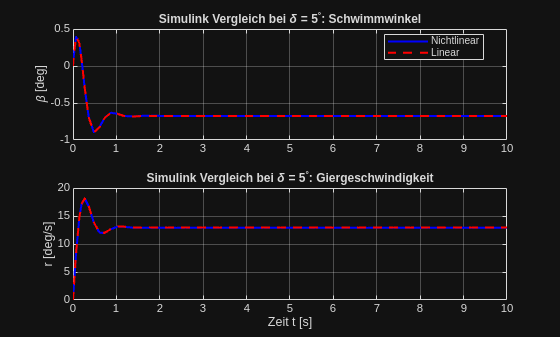


% Kombinierter Plot für 5 Grad
figure('Name', 'Vergleich bei 5°');

subplot(2,1,1); % Oberer Graph: Schwimmwinkel
plot(out_5.tout, out_5.beta_nonlinear.Data, 'b', 'LineWidth', 1.5); hold on;
plot(out_5.tout, out_5.beta_linear.Data, 'r--', 'LineWidth', 1.5);
grid on; ylabel('\beta [deg]');
title('Simulink Vergleich bei \delta = 5^\circ: Schwimmwinkel');
legend('Nichtlinear', 'Linear', 'Location', 'best');

subplot(2,1,2); % Unterer Graph: Giergeschwindigkeit
plot(out_5.tout, out_5.dpsi_nonlinear.Data, 'b', 'LineWidth', 1.5); hold on;
plot(out_5.tout, out_5.dpsi_linear.Data, 'r--', 'LineWidth', 1.5);
grid on; xlabel('Zeit t [s]'); ylabel('r [deg/s]');
title('Simulink Vergleich bei \delta = 5^\circ: Giergeschwindigkeit');



% ==========================================
% 2. Durchlauf: 20 Grad Lenkwinkelsprung
% ==========================================
delta_sim = deg2rad(20); 

% Simulink-Modell erneut starten
out_20 = sim(modellName);

% Abweichungen auslesen
err_beta_20 = out_20.max_fehler_beta(end);
err_dpsi_20 = out_20.max_fehler_dpsi(end);

fprintf('--- Ergebnisse bei 20° Lenkwinkelsprung ---\n');

--- Ergebnisse bei 20° Lenkwinkelsprung ---


fprintf('Max. Abweichung Schwimmwinkel:      %.4f°\n', err_beta_20);

Max. Abweichung Schwimmwinkel:      0.1193°


fprintf('Max. Abweichung Giergeschwindigkeit: %.4f°/s\n\n', err_dpsi_20);

Max. Abweichung Giergeschwindigkeit: 2.0524°/s



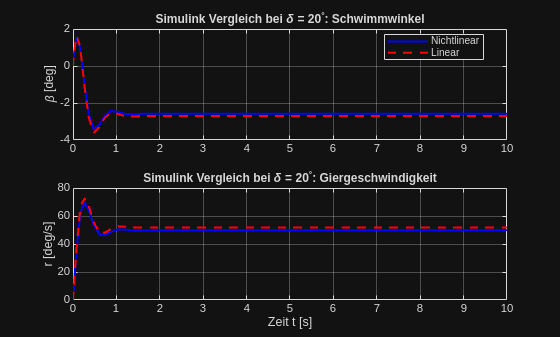


% Kombinierter Plot für 20 Grad
figure('Name', 'Vergleich bei 20°');

subplot(2,1,1); % Oberer Graph: Schwimmwinkel
plot(out_20.tout, out_20.beta_nonlinear.Data, 'b', 'LineWidth', 1.5); hold on;
plot(out_20.tout, out_20.beta_linear.Data, 'r--', 'LineWidth', 1.5);
grid on; ylabel('\beta [deg]');
title('Simulink Vergleich bei \delta = 20^\circ: Schwimmwinkel');
legend('Nichtlinear', 'Linear', 'Location', 'best');

subplot(2,1,2); % Unterer Graph: Giergeschwindigkeit
plot(out_20.tout, out_20.dpsi_nonlinear.Data, 'b', 'LineWidth', 1.5); hold on;
plot(out_20.tout, out_20.dpsi_linear.Data, 'r--', 'LineWidth', 1.5);
grid on; xlabel('Zeit t [s]'); ylabel('r [deg/s]');
title('Simulink Vergleich bei \delta = 20^\circ: Giergeschwindigkeit');

## Aufgabe 4

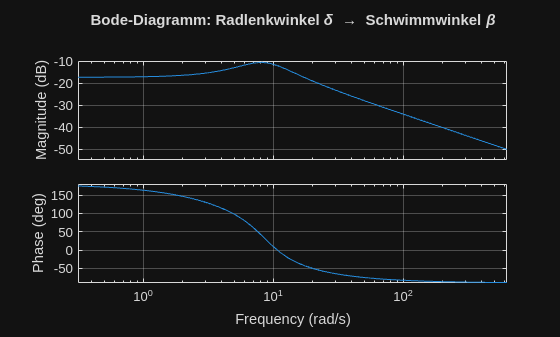

%% Aufgabe 4: Bode-Diagramm für das linearisierte Modell
% Übertragungsfunktion von delta -> beta (1. Ausgang von sys_lin)
sys_beta = sys_lin(1); 

% Frequenzbereich: 0.05 Hz bis 100 Hz
% Hinweis: Die Funktion bode() erwartet rad/s, daher mit 2*pi multiplizieren
f_start = 0.05 * 2 * pi;
f_end = 100 * 2 * pi;

figure('Name', 'Aufgabe 4: Bode-Diagramm Schwimmwinkel');
bode(sys_beta, {f_start, f_end});
grid on;
title('Bode-Diagramm: Radlenkwinkel \delta \rightarrow Schwimmwinkel \beta');


% Interpretation (für dein Live Script als Text):
% 1. Amplitudengang: Bei niedrigen Frequenzen ist die Verstärkung konstant. 
%    Mit steigender Frequenz sinkt die Amplitude (Tiefpassverhalten), da das 
%    Fahrzeug aufgrund seiner Masse und Trägheit schnellen Lenkbewegungen 
%    nicht mehr folgen kann.
% 2. Phasengang: Es tritt eine zunehmende Phasenverzögerung auf.


## Aufgabe 5

%% Aufgabe 5: Optimierung der Geschwindigkeit v
% Ziel: Die Geschwindigkeit finden, bei der beta am Ende (t=8s) Null ist.

v_start = 20; % Startwert für die Suche [m/s]

% Wir nutzen fminsearch oder fminbnd. fminsearch ist oft robuster.
options = optimset('Display','iter','TolX',1e-2);

fprintf('Starte Optimierung... Simulink wird jetzt mehrfach im Hintergrund aufgerufen.\n');

Starte Optimierung... Simulink wird jetzt mehrfach im Hintergrund aufgerufen.



% Start der Optimierung
[v_opt, final_beta_abs] = fminsearch(@(v_test) kostenfunktion(v_test, p, modellName), v_start, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1         0.867697              1            2         0.867697         initial simplex
     2            4         0.675572         expand
     3            6        0.0176043         expand
     4            8        0.0176043         contract inside
     5           10        0.0176043         contract inside
     6           12        0.0176043         contract inside
     7           14        0.0176043         contract outside
     8           16        0.0124509         contract inside
     9           18       0.00267681         contract inside
    10           20       0.00267681         contract inside
    11           22       0.00108621         contract inside
    12           24      0.000796871         contract inside
    13           26      0.000144276         contract inside
    14           28      0.000144276         contract inside
    15           30      9.10846e-05         contract inside



fprintf('\nOPTIMIERUNG FERTIG!\n');


OPTIMIERUNG FERTIG!


fprintf('Die ideale Geschwindigkeit ist: %.2f m/s (das sind %.1f km/h)\n', v_opt, v_opt*3.6);

Die ideale Geschwindigkeit ist: 13.93 m/s (das sind 50.1 km/h)


fprintf('Der restliche Schwimmwinkel beträgt nur noch: %.6f Grad\n', final_beta_abs);

Der restliche Schwimmwinkel beträgt nur noch: 0.000091 Grad


function cost = kostenfunktion(v_test, p, modellName)
    % 1. Matrizen für TEST-Geschwindigkeit v_test berechnen
    A11 = (p.cf - p.cr) / (p.m * v_test);
    A12 = (p.cr * p.lr - p.cf * p.lf) / (p.m * v_test^2) - 1;
    A21 = (p.lf * p.cf + p.lr * p.cr) / p.Jz;
    A22 = -(p.lf^2 * p.cf + p.lr^2 * p.cr) / (p.Jz * v_test);
    
    % Werte in den Workspace schreiben
    assignin('base', 'A', [A11, A12; A21, A22]);
    assignin('base', 'B', [p.cf / (p.m * v_test); (p.lf * p.cf) / p.Jz]);
    assignin('base', 'v', v_test);
    assignin('base', 'delta_sim', deg2rad(5));

    % 2. SIMULINK STARTEN
    % Wir erfassen den Output in 'simOut'
    simOut = sim(modellName, 'SrcWorkspace', 'base', 'StopTime', '8');
    
    % 3. Fehler-sicheres Auslesen des Endwerts
    raw_data = simOut.beta_linear;
    
    if isa(raw_data, 'timeseries')
        % Falls es eine Timeseries ist, brauchen wir .Data
        beta_ende = raw_data.Data(end);
    elseif isstruct(raw_data)
        % Falls es eine Struktur ist (Signals & Time)
        beta_ende = raw_data.signals.values(end);
    else
        % Falls es bereits ein numerisches Array ist
        beta_ende = raw_data(end);
    end
    
    % 4. Kosten: Betrag des Endwerts
    cost = abs(beta_ende); 
end
